## Part A: Getting the Data

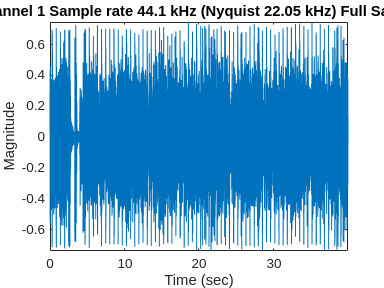

clear    % Clear all variables
close all

[music, Fs] = audioread("StayWithMeTrim.wav"); %trimmed manually to 42
music_ch1 = music(:,1);
time = (0:length(music_ch1)-1)/Fs;
figure(1)
plot(time,music_ch1);
xlabel('Time (sec)')
ylabel('Magnitude')
title('Channel 1 Sample rate 44.1 kHz (Nyquist 22.05 kHz) Full Sample')
axis tight

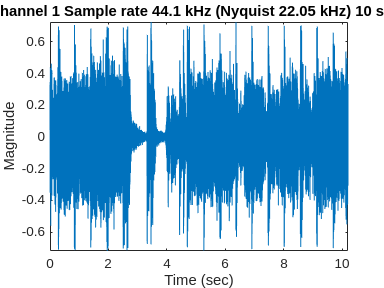


figure(2)
%trimming the data to 10s and plotting
music_10s = music_ch1(1:450000);
time_10s = (0:length(music_10s)-1)/Fs;
plot(time_10s,music_10s);
xlabel('Time (sec)');
ylabel('Magnitude');
title('Channel 1 Sample rate 44.1 kHz (Nyquist 22.05 kHz) 10 secs');
axis tight;

## Part B: Aliasing Experiments, Time-domain Observations

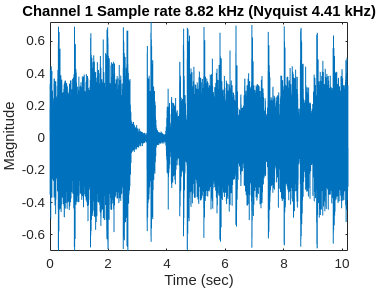

%subsampling by 5
music_by_5 =  music_10s(1:5:end);
Fs_by_5 = Fs/5;
time_by_5 = (0:length(music_by_5)-1)/Fs_by_5;
figure(3)
plot(time_by_5,music_by_5);
xlabel('Time (sec)');
ylabel('Magnitude');
title('Channel 1 Sample rate 8.82 kHz (Nyquist 4.41 kHz)');
axis tight;

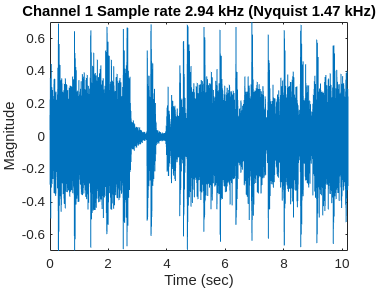

% sound(music_by_5, Fs/5)

%subsampling by 15
music_by_15 = music_10s(1:15:end);
Fs_by_15 = Fs/15;
time_by_15 = (0:length(music_by_15)-1)/Fs_by_15;
figure(4)
plot(time_by_15,music_by_15);
xlabel('Time (sec)');
ylabel('Magnitude');
title('Channel 1 Sample rate 2.94 kHz (Nyquist 1.47 kHz)');
axis tight;

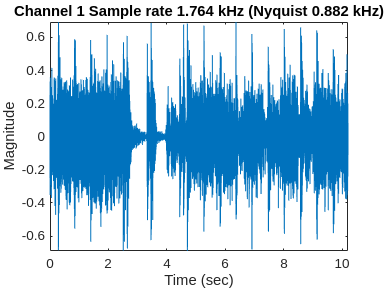

% sound(music_by_15, Fs/15)

%subsampling by 25
music_by_25 = music_10s(1:25:end);
Fs_by_25 = Fs/25;
time_by_25 = (0:length(music_by_25)-1)/Fs_by_25;
figure(5)
plot(time_by_25,music_by_25);
xlabel('Time (sec)');
ylabel('Magnitude');
title('Channel 1 Sample rate 1.764 kHz (Nyquist 0.882 kHz)');
axis tight;

% sound(music_by_25, Fs/25)

## Part B -  Aliasing Experiments, Frequency-domain Observations